clear
figure
dir = readtable("PtDirectorySimple.xlsx");
i = 1; 
dir = readtable("PtDirectorySimple.xlsx")

dir = 9×9 table
    Patient    Hemisphere            JsonSurvey                     JsonStream             StartIndex    DoubleBattery        maxBetaChan             maxThetaChan            maxGammaChan    
    _______    __________    ___________________________    ___________________________    __________    _____________    ____________________    ____________________    ____________________

       1       {'LEFT' }     {'pt1_0524_l_survey.json' }    {'pt1_0524_l_stream.json' }        7               1          {'ZERO_THREE_LEFT' }    {'ZERO_THREE_LEFT' }    {'ZERO_TWO_LEFT'   }
       1       {'RIGHT'}     {'pt1_0524_r_survey.json' }    {'pt1_0524_r_stream.json' }        7        

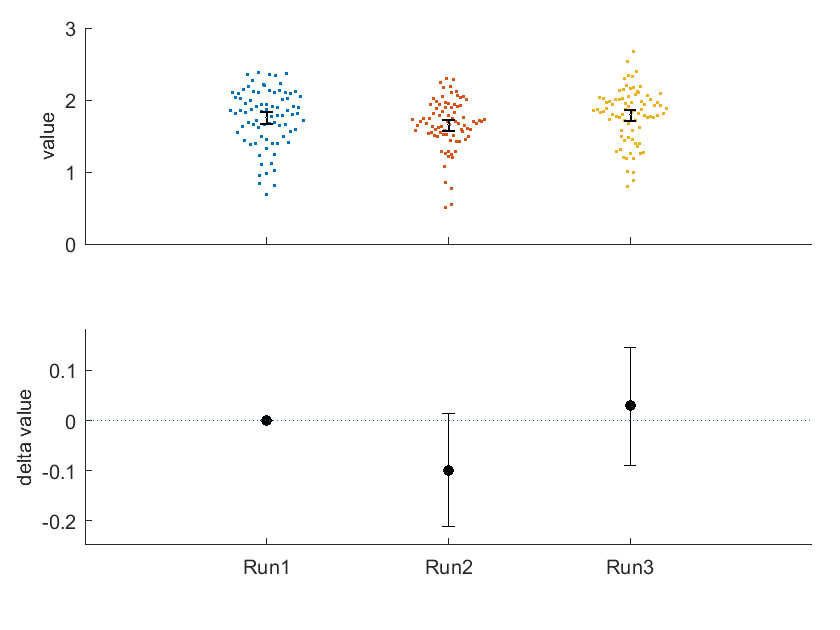

jsonFiles = dir.JsonSurvey{i};
js = jsondecode(fileread(jsonFiles));
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = dir.maxBetaChan{i};
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

oneChan = oneChanStats(outTABLE, c); 
writetable(oneChan, 'table1.csv');
outputdata = dabest('table1.csv'); 

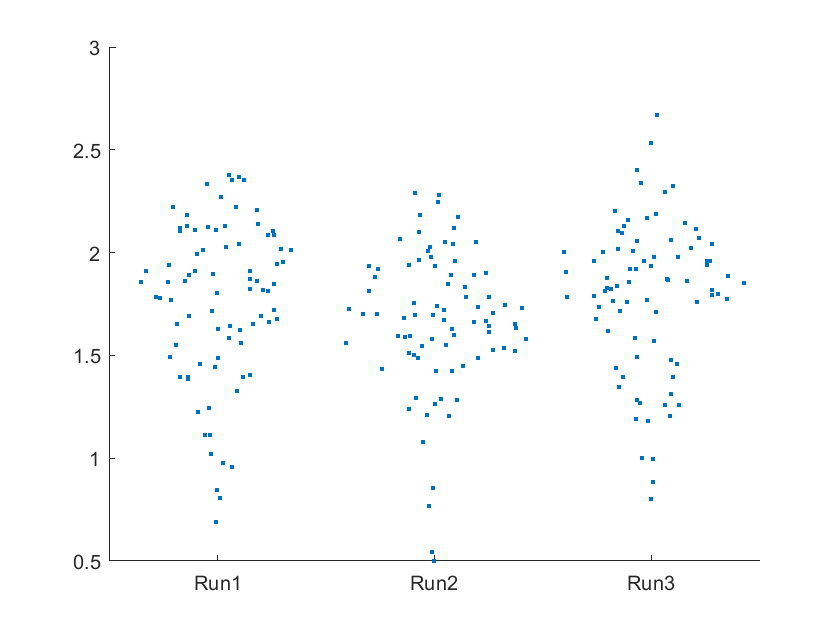

figure
names = {'Run1' 'Run2' 'Run3'}; 
x1 = categorical(oneChan.Identifiers, names);
y = oneChan.Values;
swarmchart(x1,y, '.')

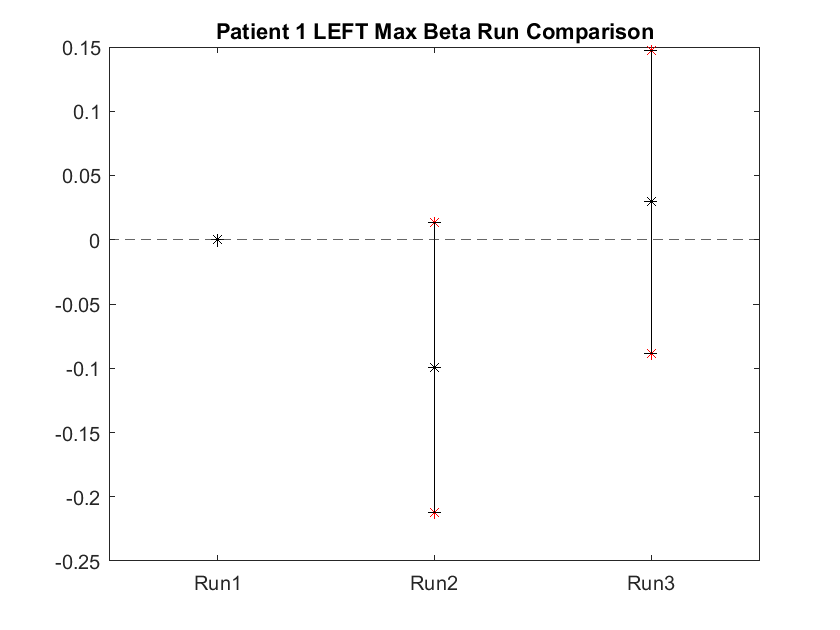


figure 
x = categorical({'Run1', 'Run2', 'Run3'}); 
%raw values 
vals = [0; outputdata(4,:).Value; outputdata(5,:).Value]; 
%first point (reference point, error is 0 by definition)
errorbar(x(1), vals(1), 0, 0, 'Color', 'black', 'Marker',"*"); 
hold on 
%r
err = outputdata(4,:).CIs;
lb = err(1);
plot(x(2), lb, 'Color', 'red', 'Marker',"*")
ub = err(2);
plot(x(2), ub, 'Color', 'red', 'Marker',"*")
errorbar(x(2), vals(2), vals(2) - lb, ub - vals(2), 'Color', 'black', 'Marker',"*"); 

err = outputdata(5,:).CIs;
lb = err(1);
plot(x(3), lb, 'Color', 'red', 'Marker',"*")
ub = err(2);
plot(x(3), ub, 'Color', 'red', 'Marker',"*")
errorbar(x(3), vals(3), vals(3) - lb, ub - vals(3), 'Color', 'black', 'Marker',"*"); 
yline(0, "LineStyle","--")
t = append("Patient ", num, " ", hemi, " Max Beta Run Comparison"); 
title(t)